## Вычисление выборочных характеристик гауссовской случайной величины (ГСВ)

clear all
close all

## Условие варианта 3b

3 - Гауссовское распределение b - Построить график зависимости значения выборочной дисперсии от числа реализаций СВ. Так же отобразить на графике значение дисперсии, вычисленное на оснвое соотношения D = sig^2

## 1. Задание исходных данных

Параметры распределения

mu = 1;
sig = 0.5;
% Параметры генерации
n = 12;     % размерность равномерной случайной величины (РСВ)
N = 1000;   % число реализаций

## 2. Вычисление значений статистических характеристик ГСВ

m = mu;     % мат. ожидание
d = sig^2;  % дисперсия
% Функция для вычисления значений плотности распределения
p = @(x) 1 / (sig * sqrt(2*pi)) * exp(-(x - mu).^2 / (2 * sig^2));

## 3. Генерация реализаций случайной величины

Генерация реализаций стандартной РСВ

alf = rand(n, N);   % матрица из N столбцов по n элементов
% Генерация реализаций ГСВ (суммирование выполняется по столбцам матрицы alf)
x = sig * (sum(alf) - 6) + mu;

## 4. Вычисление выборочных характеристик

M = mean(x);        % выборочное среднее
D = var(x);         % выборочная дисперсия
% Вывод значений теоретических и выборочных характеристик
disp('Среднее значение (теоретическое)'); 

Среднее значение (теоретическое)


disp(m);

     1



disp('Среднее значение (выборочное)');

Среднее значение (выборочное)


disp(M);

    0.9976



disp('Дисперсия (теоретическая)');

Дисперсия (теоретическая)


disp(d);

    0.2500



disp('Дисперсия (выборочная)');

Дисперсия (выборочная)


disp(D);

    0.2596



## 5. Вычисление зависимости выборочной дисперсии и выборочного среднего от числа реализаций ГСВ

Ds = zeros(1, N); % создаём массив для хранения значений выборочной дисперсии
Ms = zeros(1, N); % создаём массив для хранения значений выборочного среднего
for N_i = 1 : N
    % Генерация реализаций ГСВ (суммирование выполняется по столбцам матрицы alf_i)
    alf_i = rand(n, N_i);
    x_i = sig * (sum(alf_i) - 6) + mu;
    % Запись нового значения выборочной дисперсии
    D_i = var(x_i);
    Ds(N_i) = D_i;
    % Запись нового значения выборочного среднего
    M_i = mean(x_i);
    Ms(N_i) = M_i;
end
sizes = 1:N;
% Отрисовка зависимостей выборочной дисперсии и выборочного среднего от
% числа реализаций СВ
disp("Зависимость выборочной дисперсии от числа реализации СВ");

Зависимость выборочной дисперсии от числа реализации СВ


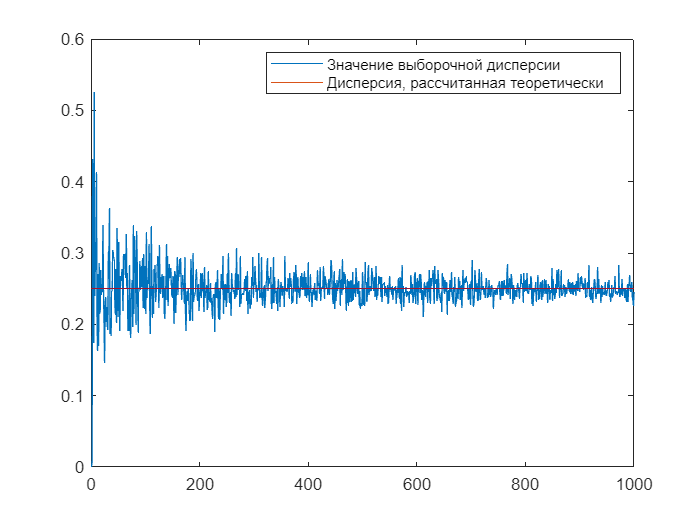

figure;
plot(Ds);
hold on;
plot(d * ones(N));
legend("Значение выборочной дисперсии", "Дисперсия, рассчитанная теоретически");


disp("Зависимость выборочного среднего от числа реализации СВ");

Зависимость выборочного среднего от числа реализации СВ


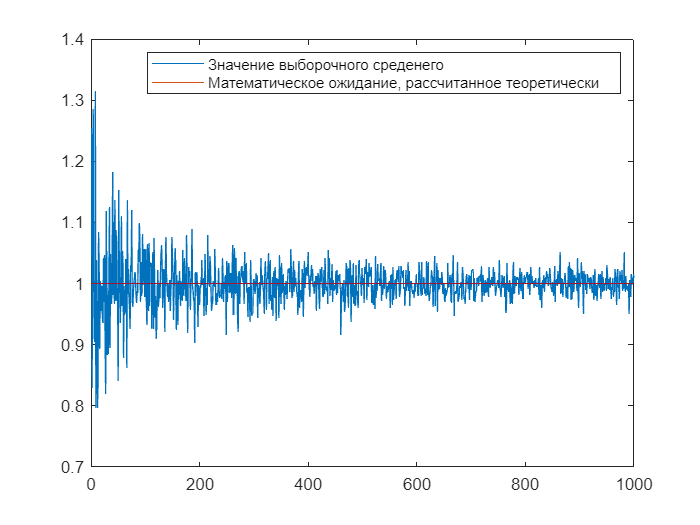

figure;
plot(Ms);
hold on;
plot(m * ones(N));
legend("Значение выборочного среденего", "Математическое ожидание, рассчитанное теоретически");

## 6. Расчёт изменения ошибки между величинами выборочного среднего и математического ожидания

% Массив разностей между выборочным средним для числа реализаций от 1 до N
M_diff = Ms - m;

% Визуализация ошибки
disp("Ошибка между величинами выборочного среднего и математического ожидания");

Ошибка между величинами выборочного среднего и математического ожидания


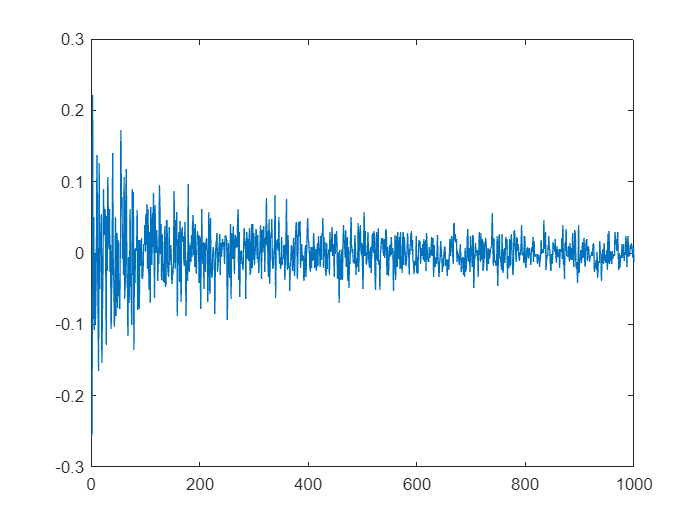

figure;
plot(M_diff);

## 7. Формирование вариационного ряда и интервалов гистограмм

Построение вариационного ряда

X = sort(x);        % упорядочивание реализаций ГСВ по возрастанию
% Вычисление размаха
RN = X(end) - X(1);
% Вывод значения размаха
disp("Размах");

Размах


disp(RN);

    3.5652



% Определение границ интервалов
h = RN / (1 + 3.2 * log2(N));   % ширина интервала
H = 1 + fix(RN / h);            % число интервалов гистограмм   
X0 = X(1) - h/2;                % нижняя граница
Xc = X(1) + h .* (0 : H - 1);   % центры интервалов
Xi = [ X0, Xc + h/2 ];          % все границы интервалов

## 8. Построение интервальной эмпирической функции распределения

Вычисление значений функции распределения

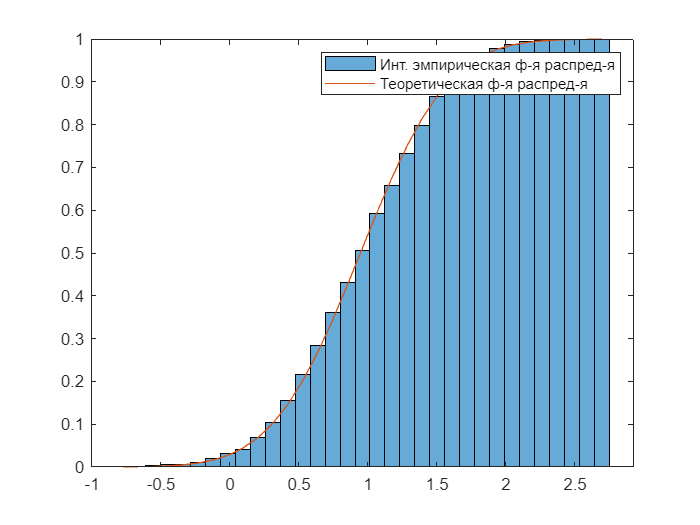

F = zeros(1, H);
for i = 1 : H
% Интеграл по плотности от нижней границы до верхней границы i-го интервала
    F(i) = integral(p, X0, Xi(i + 1));
end
% Визуализация интервальной эмпирической функции распределения
figure;         % создание нового графического окна
Fx = histogram(x, Xi, 'Normalization', 'cdf');
Fv = Fx.Values; % получение значений в ячейках
% Отрисовка теоретической функции распределения
hold on;        % включение режима дорисовки
plot(Xc, F);    % визуализация функции распределения
legend('Инт. эмпирическая ф-я распред-я', 'Теоретическая ф-я распред-я');

% Вычисление средней разности по центральным точкам интервалов
err_F = mean(abs(F - Fv));
disp('Средняя разность теоретической и эмпирической функций');

Средняя разность теоретической и эмпирической функций


disp(err_F);

    0.0054



## 9. Построение эмпирической плотности распределения

Вычисление значений плотности распределения

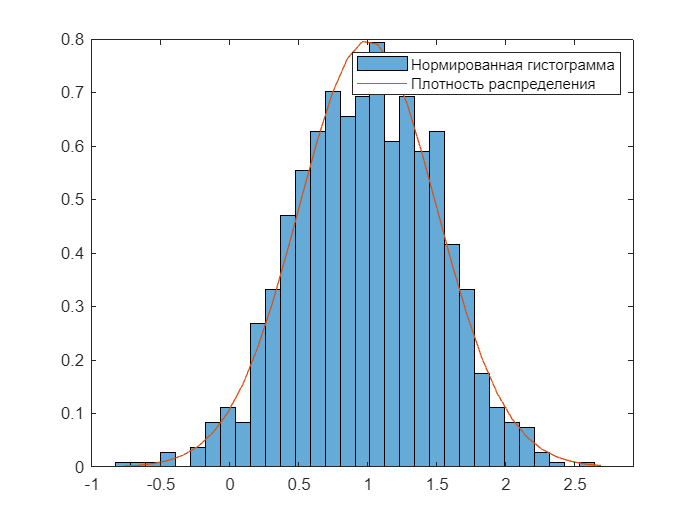

f = zeros(1, H);
for i = 1 : H
    % Значение плотности в центральной точке i-го интервала
    f(i) = p(Xc(i));
end
% Визуализация нормированной гистограммы
figure;         % создание нового графического окна
fx = histogram(x, Xi, 'Normalization', 'pdf');
fv = fx.Values; % получение значений в ячейках гистограммы
% Отрисовка плотности распределения
hold on;        % включение режима дорисовки
plot(Xc, f);    % визуализация плотности распределения
legend('Нормированная гистограмма', 'Плотность распределения');

% Вычисление средней разности по центральным точкам интервалов
err_f = mean(abs(f - fv));
disp('Средняя разность теоретической и эмпирической плотностей');

Средняя разность теоретической и эмпирической плотностей


disp(err_f);

    0.0323

